**Parameters**

DIR         = '/Volumes/DataSSD/OneDrive - UNSW/Hermite_Decomposition/ESO_HARPS/HD49933';
file_list   = dir([DIR, '/4-ccf_dat/*.dat']);
file_name   = {file_list.name};
N_FILE      = size(file_name, 2);

MJD         = importdata([DIR, '/MJD.dat']);
RV_HARPS    = importdata([DIR, '/RV_HARPS.dat']);
RV_HARPS    = (RV_HARPS - mean(RV_HARPS)) * 1000;
x           = importdata([DIR, '/x.dat']);
RV_noise    = importdata([DIR, '/RV_noise.dat']);
grid_size   = 0.1;
Fs          = 1/grid_size;
RV_gauss    = zeros(N_FILE,1);

% estimate the size of array FFT_power
dat_name    = [DIR, '/4-ccf_dat/', char(file_name(1))];
A           = importdata(dat_name);
[aa, bb, yy]= FUNCTION_FFT(A, 0.1);
size1       = length(bb);
FFT_power   = zeros(size1, N_FILE);
Y           = zeros(size1, N_FILE);

**Stacked cross correlation function**

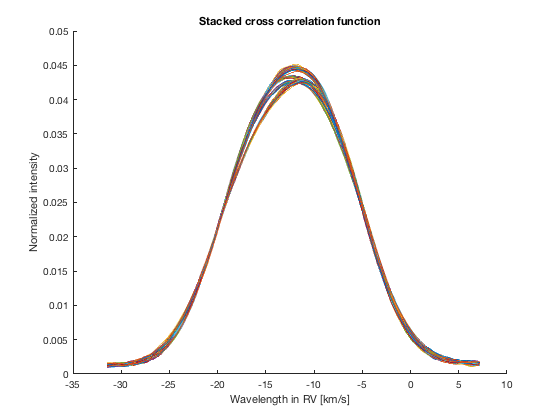

figure;
hold on
for n = 1:N_FILE

    dat_name    = [DIR, '/4-ccf_dat/', char(file_name(n))];
    A           = importdata(dat_name);
    plot(x, A)
    [FFT_frequency, FFT_power(:, n), Y(:, n)] = FUNCTION_FFT(A, Fs);
    
    % f           = fit(x, A, 'a*exp(-((x-b)/c)^2)+d', 'StartPoint', [0.5, -12, 4, 0] );
    % RV_gauss(n) = f.b;    
    
end     
% RV_gauss = (RV_gauss - mean(RV_gauss))*1000;

hold off
title('Stacked cross correlation function')
xlabel('Wavelength in RV [km/s]')
ylabel('Normalized intensity')
saveas(gcf,'1-Line_Profile','png')

**FT power in all epochs**

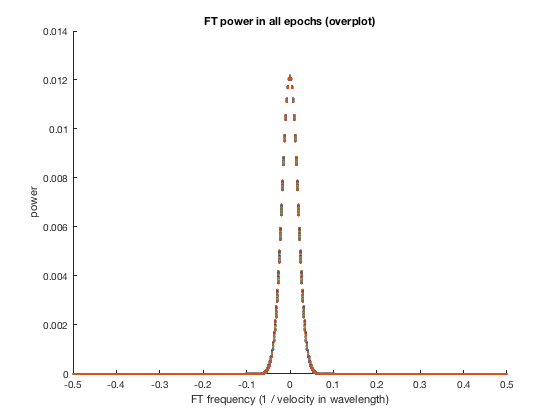

figure;
hold on
for n = 1:N_FILE
%     plot(FFT_frequency, FFT_power(:, n) - FFT_power(:, 51), '-')
%     title('Differential FT power in all epochs (overplot)')
%     xlabel('FT frequency (1 / velocity in wavelength)')
%     ylabel('Differential power') 
    
    plot(FFT_frequency, FFT_power(:, n), '.')
    title('FT power in all epochs (overplot)')
    xlabel('FT frequency (1 / velocity in wavelength)')
    ylabel('power')   
    xlim([-0.5 0.5])
end 
hold off
saveas(gcf,'2-FT_power','png')
saveas(gcf,'2-Differential_FT_power','png')

**Phase angle**

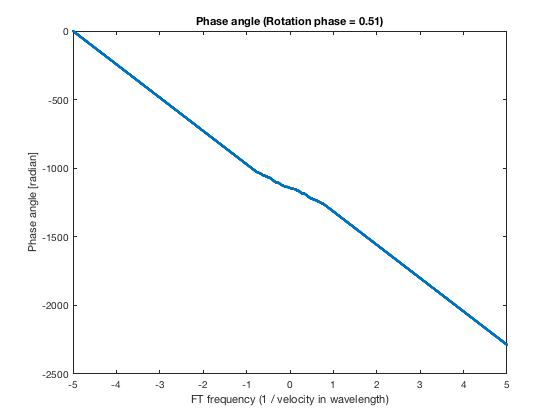

figure;
plot(FFT_frequency, unwrap(angle(Y(:, 51))), '.')
title('Phase angle (Rotation phase = 0.51)')
xlabel('FT frequency (1 / velocity in wavelength)')
ylabel('Phase angle [radian]')
% xlim([-0.35 0.35])
saveas(gcf,'3-Phase_angle','png')

**Phase angle -> RV **

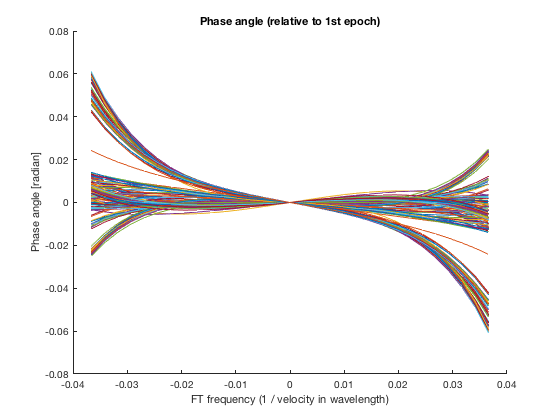

slope = zeros(1,N_FILE)';
RV_FT = zeros(1,N_FILE)';
figure; 
hold on
for i = 1:N_FILE
    n = (size(FFT_frequency,2)/2+1-15):(size(FFT_frequency,2)/2+1+15);
    xx = FFT_frequency(n);
    yy = (angle(Y(n, i)) - angle(Y(n, 1)))';
    plot(xx, yy, '-')
    title('Phase angle (relative to 1st epoch)')
    xlabel('FT frequency (1 / velocity in wavelength)')
    ylabel('Phase angle [radian]')

    % Phase angle -> RV
    weight = FFT_power(n,i)';
    [fitresult, ~] = 4(xx, yy, weight);
    slope(i) = fitresult.p1;
    RV_FT(i) = -slope(i) / (2*pi);
end
hold off
saveas(gcf,'4-Relative_phase_angle','png')


RV_FT = (RV_FT - mean(RV_FT)) * 1000;


**Time sequence**

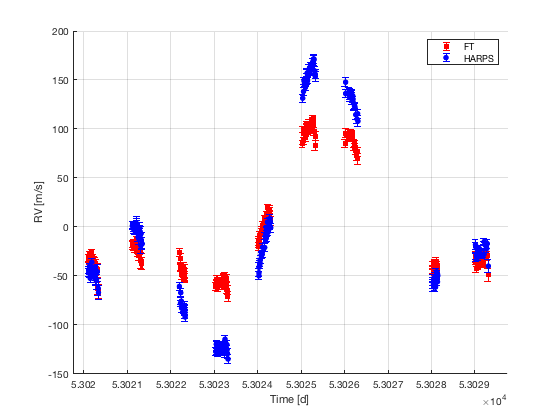

idx_t   = (MJD>53019) & (MJD<53030);
MJD     = MJD(idx_t);
RV_HARPS= RV_HARPS(idx_t);
RV_FT   = RV_FT(idx_t);
RV_noise= RV_noise(idx_t);

figure; 
hold on
errorbar(MJD, RV_FT, RV_noise , 'rs', 'MarkerSize', 5, 'MarkerFaceColor', 'r')
errorbar(MJD, RV_HARPS, RV_noise , 'b.', 'MarkerSize', 16)
% errorbar(MJD, jitter_model, RV_noise/alpha, 'k.', 'MarkerSize', 10)
% errorbar(MJD, RV_HARPS - jitter_model, RV_noise/alpha, 'k.', 'MarkerSize', 5)
grid on
hold off
xlabel('Time [d]')
ylabel('RV [m/s]')
xlim([53019.75 53029.75])
legend('FT', 'HARPS')
saveas(gcf,'5-Time_sequence','png')

**Mean time sequence**

%sum(w.*x,dim)./sum(w,dim);

**Jitter model**

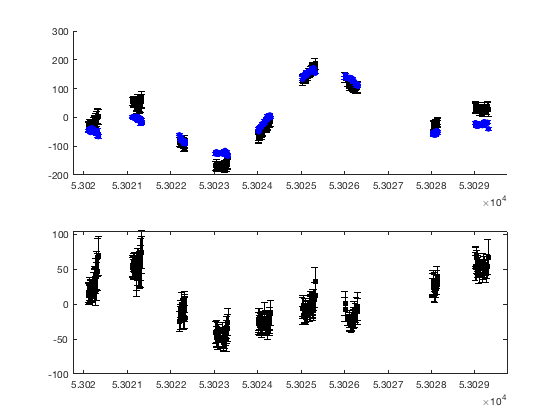

jitter_proto = RV_HARPS - RV_FT;
[fitresult, gof] = createFit(RV_HARPS, jitter_proto, (1./RV_noise.^2));
alpha   = fitresult.p1;
beta    = fitresult.p2;
jitter_model = (jitter_proto - beta) / alpha;

figure;
subplot(2,1,1)
hold on
errorbar(MJD, jitter_model, sqrt(2)*RV_noise / alpha, 'ks', 'MarkerSize', 5, 'MarkerFaceColor', 'k')
errorbar(MJD, RV_HARPS, RV_noise , 'b.', 'MarkerSize', 16)
xlim([53019.75 53029.75])
hold off
subplot(2,1,2)
errorbar(MJD, jitter_model - RV_HARPS, RV_noise * sqrt(2/alpha^2+1), 'ks', 'MarkerSize', 5, 'MarkerFaceColor', 'k')
xlim([53019.75 53029.75])

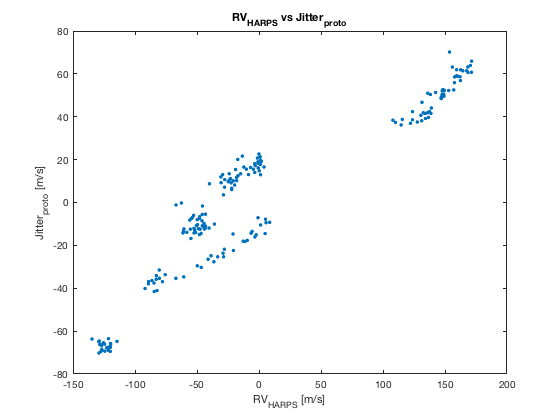




figure; 
plot(RV_HARPS, jitter_proto, '.', 'MarkerSize', 10)
% plot(RV_HARPS, RV_FT25*3 - RV_FT20, '.', 'MarkerSize', 10)
title('RV_{HARPS} vs Jitter_{proto}')
xlabel('RV_{HARPS} [m/s]')    
ylabel('Jitter_{proto} [m/s]')
saveas(gcf,'6-HARPS_vs_Jitter','png')


dlmwrite('RV_jitter.txt', jitter_proto)

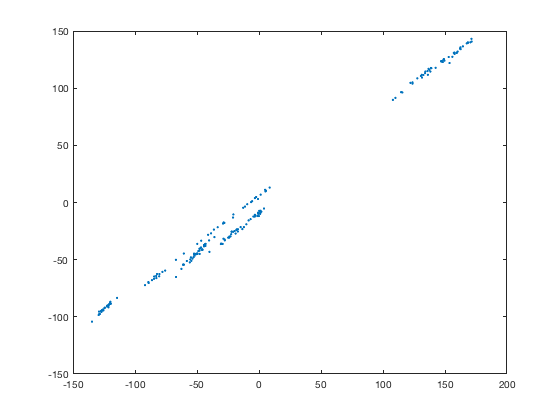



plot(RV_HARPS, RV_FT, '.')